%%% Variables %%%
ks = 200;
b = .5;
kp = 15;
tau = .07;
sys = tf(ks,[b*tau,b+tau*(ks+kp),ks+kp]);

Fs = 1e5;
t = 0:1/Fs:.8;

hz = 80;
pulsewidth = .005;
pulseperiods = [0:1/hz:.8];


%%% Part a %%%
x = pulstran(t,pulseperiods,@rectpuls,pulsewidth)/10;
x(t>0.2 & t<0.205) = 0.1

x =     0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000


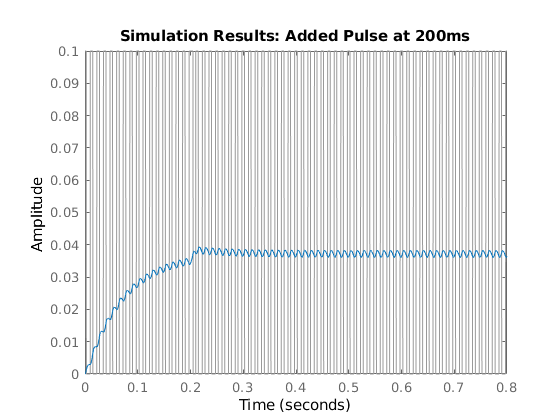

lsim(sys,x,t)
title('Simulation Results: Added Pulse at 200ms')


%%% Part b %%%
x(t>0.2 & t<0.205) = 0.0

x =     0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000


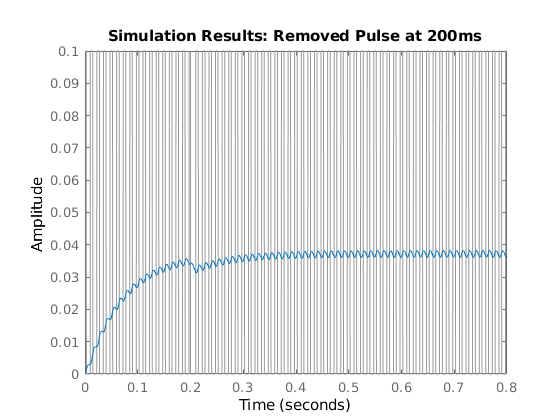

lsim(sys,x,t)
title('Simulation Results: Removed Pulse at 200ms')


%%% Part c %%%
x = pulstran(t,pulseperiods,@rectpuls,pulsewidth)/10;
x(t>0.0038 & t<0.0088) = 0.1

x =     0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000


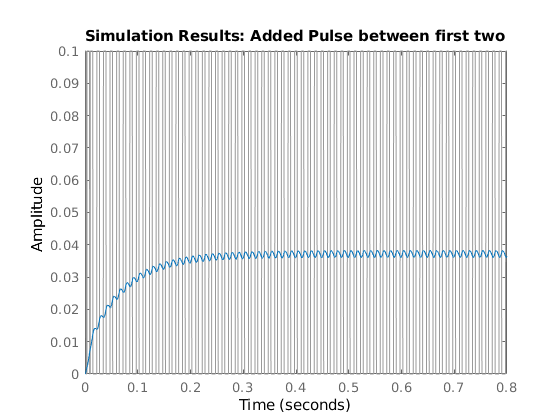

lsim(sys,x,t)
title('Simulation Results: Added Pulse between first two')